# The Post

[ ](https://matlab.mathworks.com/open/github/v1?repo=simulink/blog&project=2026_04_20_WhatsNew_R2026a/WhatsNew_R2026a.prj)

MATLAB R2026a is available, let's see what's new in the Simulink world.

## New Context Menu

That one cannot be missed! We decided to modernize our right-click menu.

Here is what it looks like when you right-click on a Constant block:

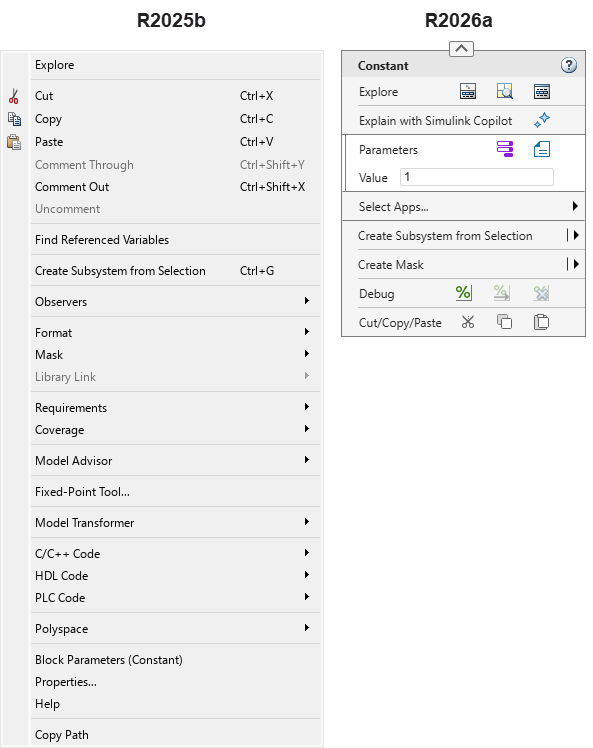

I have been using this new menu for many months now and it works well for me. It takes a little bit of getting used to, but overall, I think this is a good evolution.

See the [release notes](https://www.mathworks.com/help/simulink/release-notes.html#mw_30afebc1-3924-4012-bdf8-3ee037f7a580) for more details.

## Move In/Move Out

This one will save me so many clicks!

Select blocks connected to a Subsystem and move them in, in one click. 

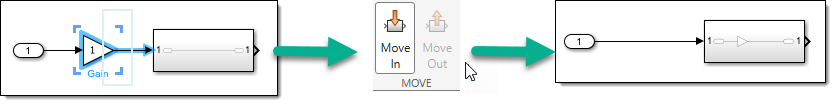

Select blocks connected to an Inport or Outport inside a subsystem and move them out, in one click.

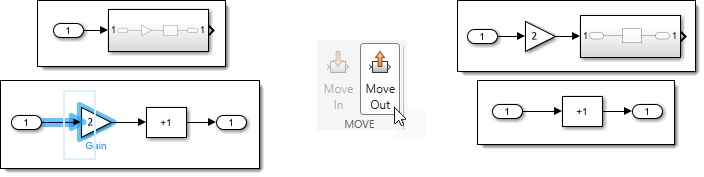

## Time Tolerance to input Data

Throughout the years, one blog post that I had to refer to more often than I would like is this one: [Using Discrete Data as an input to your Simulink model » Guy on Simulink - MATLAB & Simulink](https://blogs.mathworks.com/simulink/2012/02/09/using-discrete-data-as-an-input-to-your-simulink-model/).

To summarize: If you specify time points for input signals that are slightly different from the time steps that Simulink takes, you will end up with skipped or duplicated points.

This new feature finally solves this issue. Let's revisit the example from this old post with and without the feature activated.

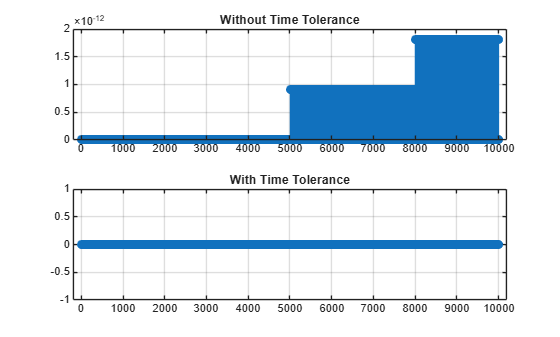

ts = 0.001;
t = (0:ts:10)';
u = (1:length(t))';
mdl = 'testInputTol';
in = repmat(Simulink.SimulationInput(mdl),2,1);
in(1) = in(1).setModelParameter('InputTimeTolerance','off');
in(2) = in(2).setModelParameter('InputTimeTolerance','on');
out = sim(in,'ShowProgress','off');
figure;
subplot(2,1,1);
stem(abs(u-out(1).logsout.get('u').Values.Data));
title("Without Time Tolerance");
subplot(2,1,2);
stem(abs(u-out(2).logsout.get('u').Values.Data));
title("With Time Tolerance");

Minor related addition, [external input signal can now contain Inf and NaN](https://www.mathworks.com/help/simulink/release-notes.html#mw_e62d2279-2cb2-4edb-aae7-da850055f25d).

## Rapid Accelerator is Rapider

I hope you know that Simulink has a Rapid Accelerator mode. The way it works, it compiles the model into an executable, and that executable usually runs faster than the original.

One problem is that, with small models, launching this executable takes longer 1-2 seconds. If you need to run a million of those, it's 1-2 million seconds lost. In R2026a, this initial launch time has been significantly speeding up short simulations.

Here is an example:

mdl = 'vdp';
Simulink.BlockDiagram.buildRapidAcceleratorTarget(mdl);

### Searching for referenced models in model 'vdp'.
### Total of 1 models to build.


kv = 1:0.1:1.9;
in = repmat(Simulink.SimulationInput(mdl),length(kv),1);
for i = 1:length(kv)
    in(i) = in(i).setVariable('k',kv(i));
    in(i) = in(i).setModelParameter('SimulationMode','Rapid');
    in(i) = in(i).setModelParameter('RapidAcceleratorUpToDateCheck','off');
end
out = sim(in,'ShowProgress','off','UseFastRestart','on');
t = arrayfun(@(i) out(i).SimulationMetadata.TimingInfo.TotalElapsedWallTime,1:length(kv));
mean(t(2:end))

ans = 0.3678

In older releases, the same code gives me an average execution time of 2.3 seconds.

On a slightly related topic, in R2026a, it also becomes possible to [simulate models with algebraic loops in Rapid Accelerator mode](https://www.mathworks.com/help/simulink/release-notes.html#mw_9be53954-407d-45c2-9734-9a8336009a76).

## Initialization Timing in Simulink Profiler

The [Simulink Profiler](https://www.mathworks.com/help/simulink/slref/simulinkprofiler.html) now provides information about how compilation time is distributed among compilation phases and among referenced model.

It's an enhanced version of the `CompileStats` captured by [`sldiagnostics`](https://www.mathworks.com/help/simulink/slref/sldiagnostics.html). If you call technical support about problems with initialization performance, this is the first thing we will ask you to look at.

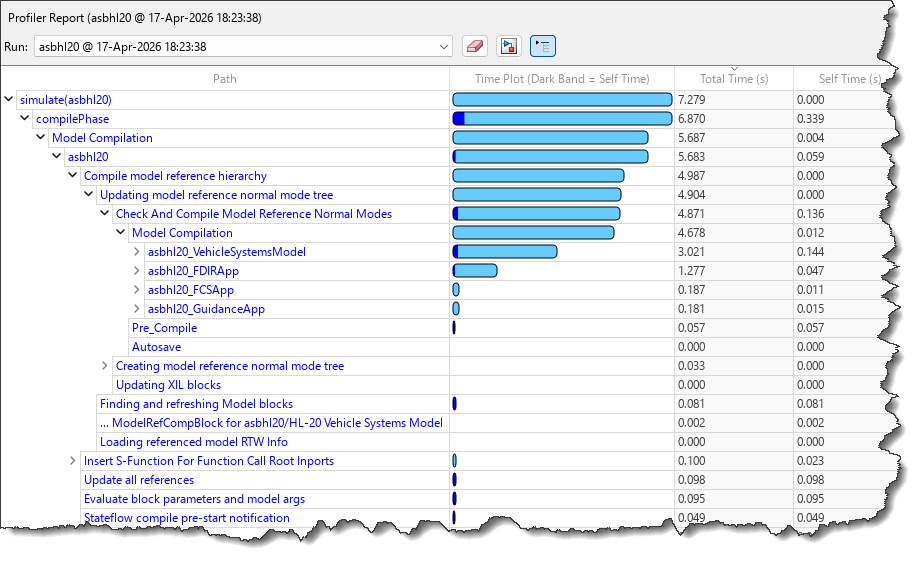

## Self-Paced Training

A new set of self-paced training to get you started with many basic aspects of Simulink:

- [The Simulink Environment | Self-Paced Online Courses - MATLAB & Simulink](https://matlabacademy.mathworks.com/details/the-simulink-environment/otslse)

- [Model Dynamic Systems | Self-Paced Online Courses - MATLAB & Simulink](https://matlabacademy.mathworks.com/details/model-dynamic-systems/otslmds)

- [Run Multiple Simulations in Parallel | Self-Paced Online Courses - MATLAB & Simulink](https://matlabacademy.mathworks.com/details/run-multiple-simulations-in-parallel/otmlslrmsp)

- [Configure Simulink Solvers to Improve Performance | Self-Paced Online Courses - MATLAB & Simulink](https://matlabacademy.mathworks.com/details/configure-simulink-solvers-to-improve-performance/otslosp)

- [Componentization Techniques for Simulink Models | Self-Paced Online Courses - MATLAB & Simulink](https://matlabacademy.mathworks.com/details/componentization-techniques-for-simulink-models/otslcbm)

- [Create Model Hierarchy with Subsystems | Self-Paced Online Courses - MATLAB & Simulink](https://matlabacademy.mathworks.com/details/create-model-hierarchy-with-subsystems/otslcmhs)

- [Model System Components | Self-Paced Online Courses - MATLAB & Simulink](https://matlabacademy.mathworks.com/details/model-system-components/otslmsc)

- [Analyzing Results in Simulink | Self-Paced Online Courses - MATLAB & Simulink](https://matlabacademy.mathworks.com/details/analyzing-results-in-simulink/otslars)

## Now it's your turn

Check the [Simulink release notes](https://www.mathworks.com/help/simulink/release-notes.html) and let us know what's your favorite addition in R2026a, and if there is any topics you would like to be covered on this blog.